# Son 3: Enregistrement de voix humaine et musique

Tel que pour le son 1 et 2, un bruit blanc gaussien sera ajouté. Cette fois-ci le bruit sera ajouté à un enregistrement musicale, c'est-à-dire un mélange de voix humaine et de musique. Le but est de  voir si les filtres implémentés pour la voix humaineseulement sont autant efficaces pour la filtration avec des fréquences plus riches.

La fréquence fondamentale de la voix humaine se situe entre [85 180] Hz pour les hommes et [165 , 255] Hz  pour les femmes.  En contre partie, la musique comprend une gamme de fréquences beaucoup plus étendu. Ce qui va rendre difficile de filtrer le bruit et de conserver l'integrité du signal d'entrée. 

Hypothèse I  : 

            Les filtres seront efficaces pour récuprer la majorité des fréquences vocales mais les                          frequences musicales seront grandement atténués, voir imperceptibles, sans apporter des modifications aux fréquences de coupures. Les  modifications pour une bande passante plus grande pour conserver les fréquences musicales vont engendrer qu'une partie du bruit qui va subsister dans la bande passante. Cet effet sera génaral pour l'ensemble des filtres utilisés à l'exeption du filtre peigne ainsi que la réduction par méthode des wavelets.

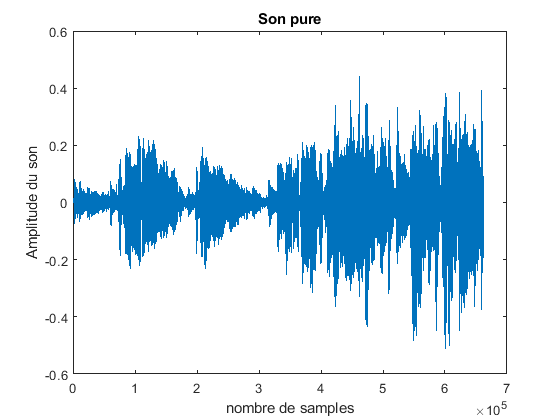

%% Exemple avec un signal de voix et musique 


clear all;
close all;
clc;
format short eng


used_time = 15; % temps en secondes

delay_time = 30 ;% temps en delais en [s] laisser écouler x secs avant échantillionnage
frequencyLimits = [0 24000]; % [Hz]   Seuil de l'audition humaine approx

%% Extraction du signal

% [son_3_sans_perturbation,sampleRate] = audioread('raspoutine.mp4'); Used to
% exctract sampleRate from original file

% sampleRate est statique a 44100 et sera donc declare de facon staique
sampleRate = 44100;
%time_total = (length(son_3_sans_perturbation)/ sampleRate); % temps en secondes

delay_points = delay_time*sampleRate; % Number of samples to skip 

cropped_sound = audioread('The Sound of Silence - Simon & Garfunkel.mp3',[(1+delay_points) (sampleRate*used_time+delay_points)]);

audiowrite('Block\cropped_sound.wav',cropped_sound,sampleRate);
%sound(cropped_sound,sampleRate); % ecouter son sans perturbation

sample_point=1:1:length(cropped_sound);
%% ajout du bruit gaussien
range = 200;
SNR = 0; % signal-to-noise ratio


% Le son sera perturbé deux fois afin d'augmenter la quantité de bruit 
son_3_avec_perturbation = awgn(cropped_sound, SNR,  'measured');
son_3_avec_perturbation = awgn(son_3_avec_perturbation, SNR,  'measured');



%% Plots PURE sans perturbation
figure
plot(sample_point,cropped_sound(:,1));
title('Son pure')
xlabel('nombre de samples')
ylabel('Amplitude du son')

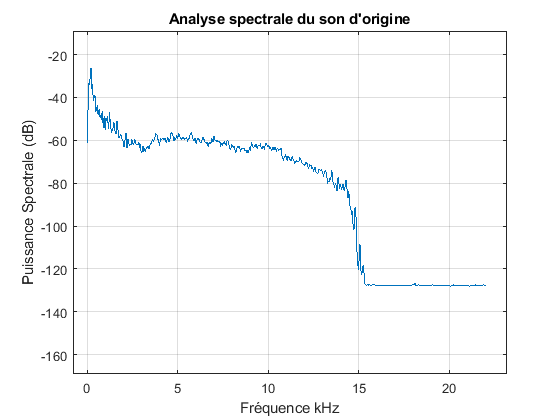



figure
SpectralAnalyser(cropped_sound(:,1),sampleRate,frequencyLimits,0,[0 15]);
title('Analyse spectrale du son d''origine')

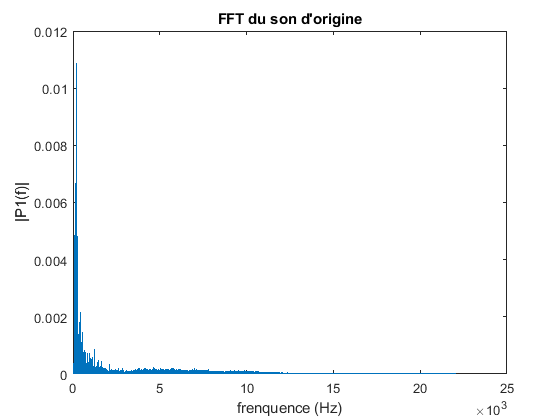


figure
fftPlotter(cropped_sound(:,1),sampleRate);
title('FFT du son d''origine')

Dans l'anyse spectrale du son pure, il est possible de voir que la puissance du signal grandement réduite à partir de 15 kHz et deviennes aboslument négligeable vers 16 kHz. Cela est facilement explicable au fait que le signal est extrait d'un fichier ".mp3".  Ces fichiers sont reconnue pour avoir une plage fréquencielle limité qui arrête à 16 kHz. Cela nous indiques aussi qu'après l'ajout du bruit Gaussien toutes les fréquences supérieures à 16 kHz sont en faites du bruit pure.   

## Son avec perturbation

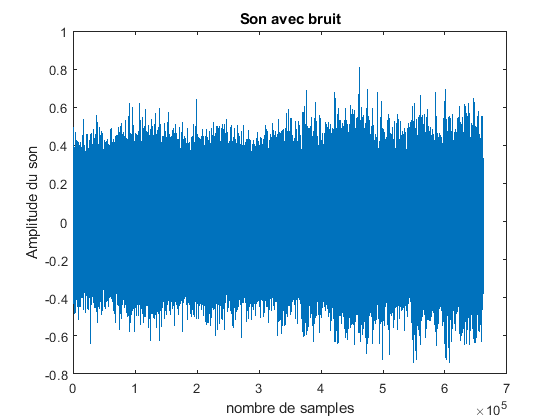


figure
plot(sample_point,son_3_avec_perturbation(:,1));
title('Son avec bruit')
xlabel('nombre de samples')
ylabel('Amplitude du son')

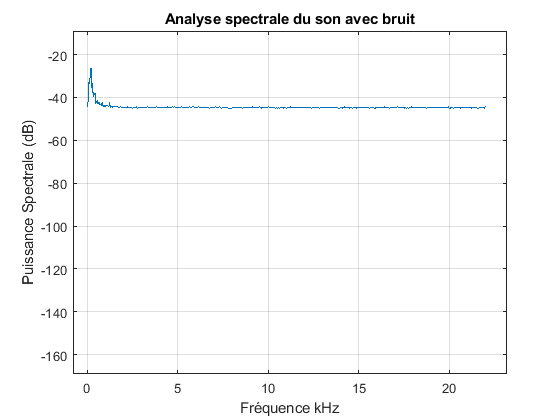


figure
SpectralAnalyser(son_3_avec_perturbation(:,1),sampleRate,frequencyLimits,0,[0 15]);
title('Analyse spectrale du son avec bruit')

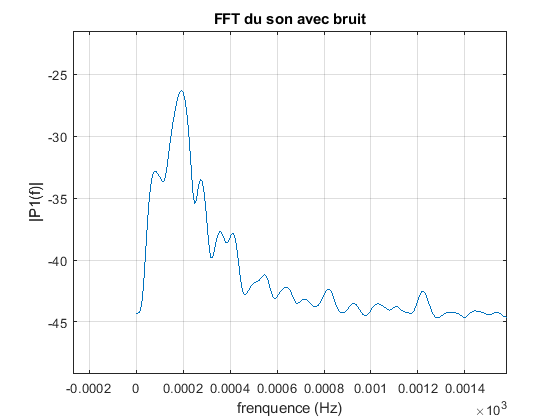



figure
SpectralAnalyser(son_3_avec_perturbation(:,1),sampleRate,frequencyLimits,0,[0 15]);
title('Analyse spectrale du son avec bruit ')

xlim([-0.27 1.58])
ylim([-49.2 -21.5])

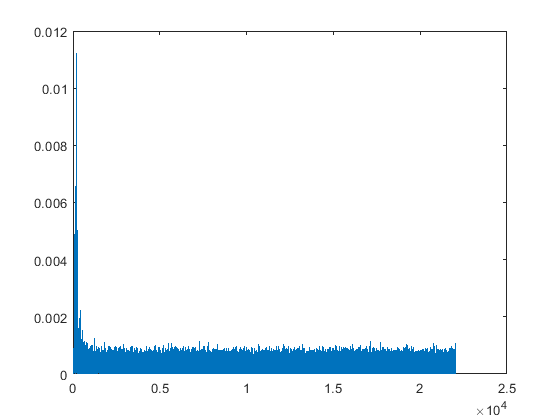



fftPlotter(son_3_avec_perturbation(:,1),sampleRate)

title('FFT du son avec bruit')

%sound(son_3_avec_perturbation,sampleRate);
%audiowrite('Block\son_3_avec_perturbation.wav',son_3_avec_perturbation,sampleRate);

En effectuant l'analyse spectrale du signal avec les perturbations, le bruit et le son s'entremêlent pour devenir imperceptibles à une fréquence 1.25 kHz d'un point de vue puissance. Nous savons donc que d'un point de vue fréquenciel. le filtres qui laissent passer des fréquences supérieures à cette fréquence critique auront aussi beaucoup de perturbation en sortie.

## Application d'un filtre passe-bas

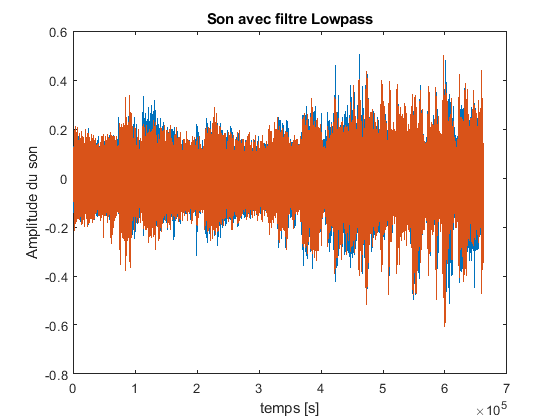


freq_coupure_lowpasse = 1250; % fréquence trouvé par essais erreur. Ce qui corrobore les conclusions de l'analyse spectrale

son_3_filtre_lowpass = lowpass(son_3_avec_perturbation,freq_coupure_lowpasse,sampleRate);

figure
plot(sample_point,son_3_filtre_lowpass)
title('Son avec filtre Lowpass')
xlabel('temps [s]')
ylabel('Amplitude du son')

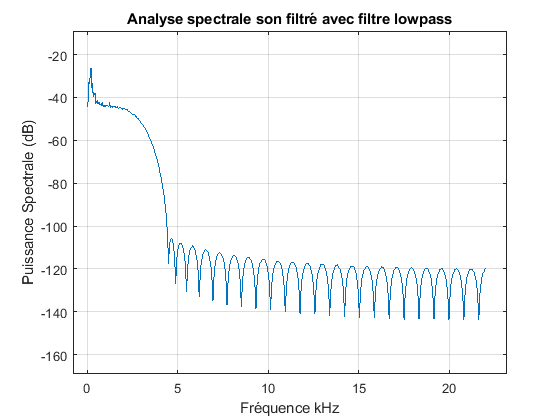


figure
SpectralAnalyser(son_3_filtre_lowpass(:,1),sampleRate,frequencyLimits,0,[0 15]);
title('Analyse spectrale son filtré avec filtre lowpass');

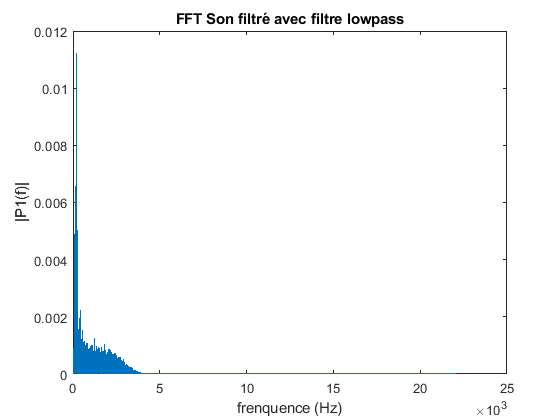


figure
fftPlotter(son_3_filtre_lowpass,sampleRate)
title('FFT Son filtré avec filtre lowpass');


%sound(son_3_filtre_lowpass,sampleRate);
%audiowrite('Block\son_3_filtre_lowpass.wav',son_3_filtre_lowpass,sampleRate);

Par essais erreur, une fréquences 1.3 kHz a été isolé cela corrobore les résultrats de l'analyse spectrale. 

 À l'écoute, l'application du filtre lowpass est démontre une amélioration de la qualtié du signal par rapport au signal bruité. Nous savons donc que le la majorité du signal se situe bel et bien dans la plage de fréquences de 20 Hz à 1250 Hz du spectre. Nous tenterons donc d'isoler ces fréquences pour avoir un maximum de fidelité du signal.

Essayons maintenant le même filtre passe passebande  qu'utilisé pour le son 2  avec des fréquences [20 600] et comparons comparons le avec un autre filtre  avec la nouvelle plage déterminé avec la section plus haute de  [20 1250] Hz

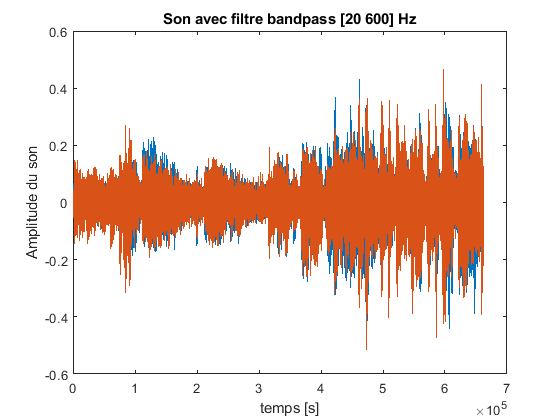

son_2_filtre_bandpass2 = bandpass(son_3_avec_perturbation,[40 600],sampleRate);


%% plot filtre bandpass [20 600] Hz

figure
plot(sample_point,son_2_filtre_bandpass2)
title('Son avec filtre bandpass [20 600] Hz')
xlabel('temps [s]')
ylabel('Amplitude du son')

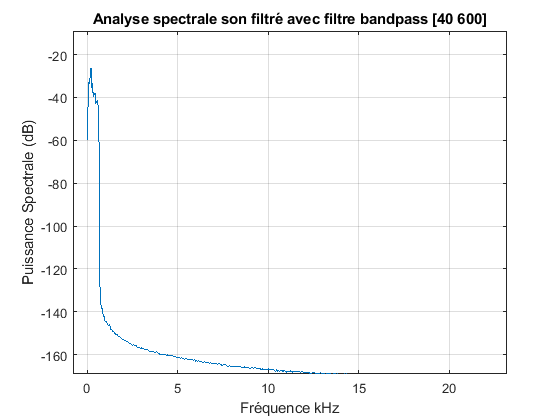


figure
SpectralAnalyser(son_2_filtre_bandpass2(:,1),sampleRate,frequencyLimits,0,[0 15]);
title('Analyse spectrale son filtré avec filtre bandpass [40 600]');

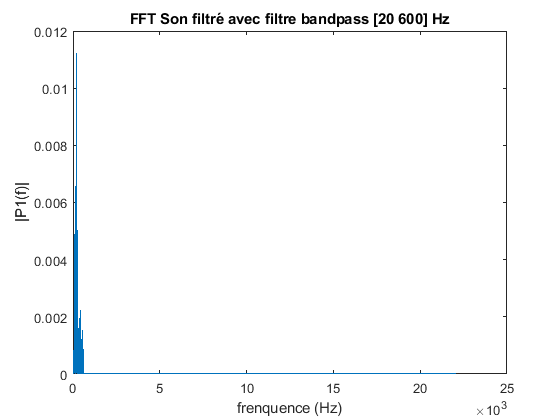


figure
fftPlotter(son_2_filtre_bandpass2,sampleRate)
title('FFT Son filtré avec filtre bandpass [20 600] Hz');

%hold on
%figure


%sound(son_2_filtre_bandpass2,sampleRate);
%audiowrite('Block\son_2_filtre_bandpass2.wav',son_2_filtre_bandpass2,sampleRate);


Appliqu'on un gain pour compenser les pertes fréquenciels 

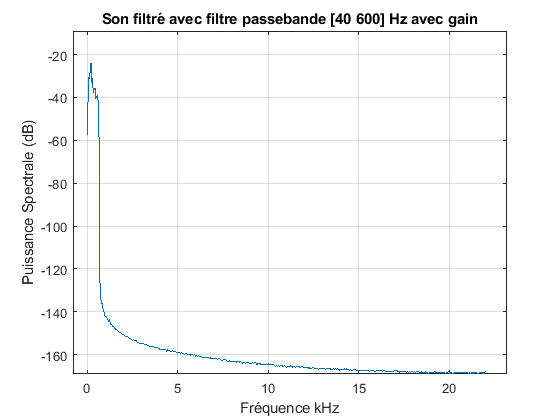

son_2_filtre_bandpass2_2 = son_2_filtre_bandpass2*1.3; % application d'un gain

figure
SpectralAnalyser(son_2_filtre_bandpass2_2,sampleRate,frequencyLimits,0,[0 15]);
title('Son filtré avec filtre passebande [40 600] Hz avec gain')

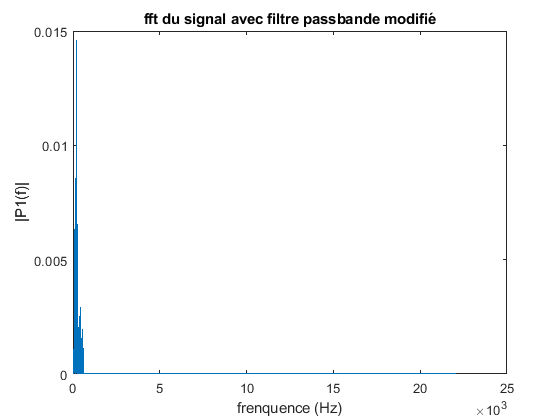


figure 
fftPlotter(son_2_filtre_bandpass2_2,sampleRate);
title('fft du signal avec filtre passbande modifié')


%sound(son_2_filtre_bandpass2_2,sampleRate);
%audiowrite('Block\son_2_filtre_bandpass2_2.wav',son_2_filtre_bandpass2_2,sampleRate);


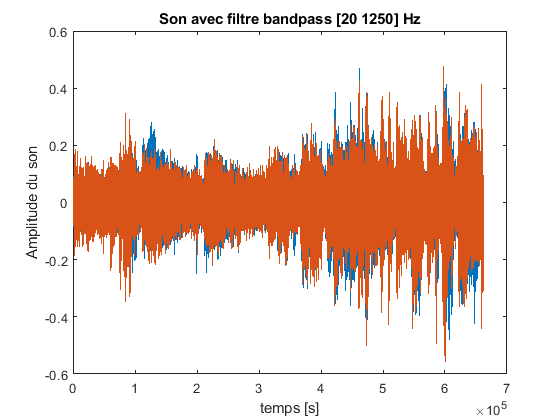

son_2_filtre_bandpass3 = bandpass(son_3_avec_perturbation,[20 1250],sampleRate);


%% plot filtre bandpass [20 1250] Hz

figure
plot(sample_point,son_2_filtre_bandpass3)
title('Son avec filtre bandpass [20 1250] Hz')
xlabel('temps [s]')
ylabel('Amplitude du son')

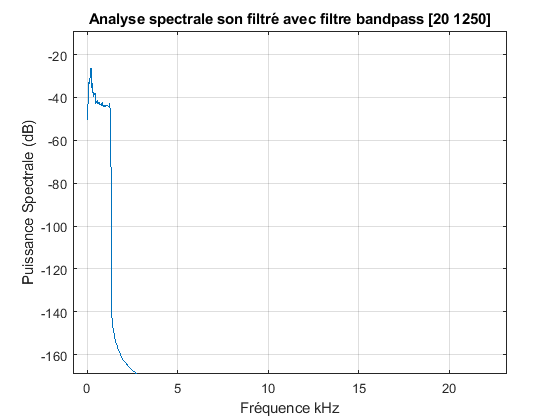


figure
SpectralAnalyser(son_2_filtre_bandpass3(:,1),sampleRate,frequencyLimits,0,[0 15]);
title('Analyse spectrale son filtré avec filtre bandpass [20 1250]');

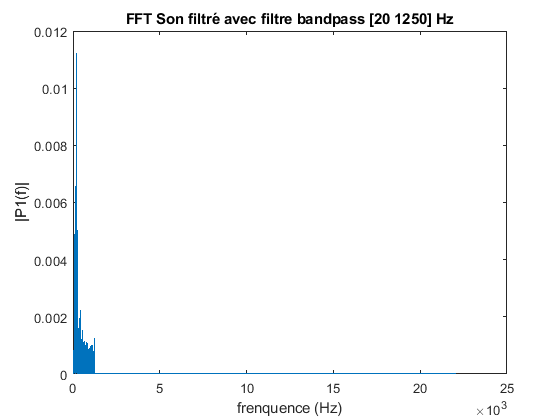


figure
fftPlotter(son_2_filtre_bandpass3,sampleRate)
title('FFT Son filtré avec filtre bandpass [20 1250] Hz');

%hold on
%figure


%sound(son_2_filtre_bandpass3,sampleRate);
%audiowrite('Block\son_2_filtre_bandpass3.wav',son_2_filtre_bandpass3,sampleRate);


En écoutant les siganux de sortie des filtres filtres passe bande, il est possible de confirmer l'hypothèse I. Pour conserver la fidlité de la musique as pour effet de conserver le bruit qui été ajouté au signal.

Le tout est donc de faire une compromis entre la fidelité et la supression des parasites.

## Comb filter

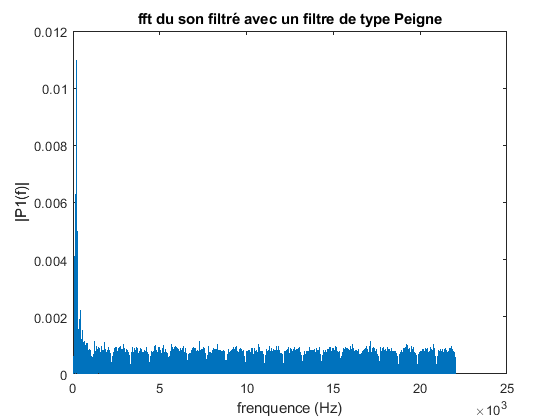



N     = 40 ;   % Order
BW    =  1000;% Bandwidth
Apass = 3;    % Bandwidth Attenuation

[b, a] = iircomb(N,...
    BW/(sampleRate/2),...
    Apass, 'peak');


combFilt    = dfilt.df2(b, a);

resComb = filter(combFilt,son_3_avec_perturbation);
figure
fftPlotter(resComb,sampleRate);
title('fft du son filtré avec un filtre de type Peigne')

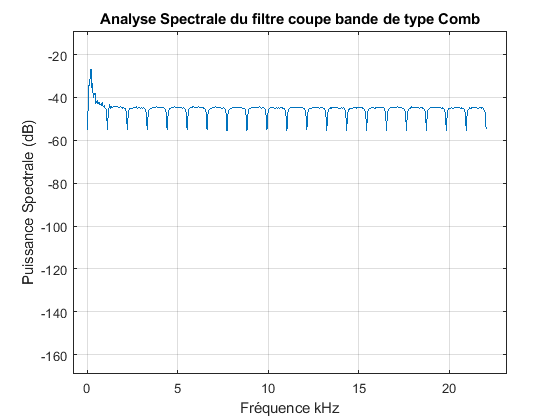


figure
SpectralAnalyser(resComb(:,1),sampleRate,frequencyLimits,0,[0 15]);
title(['Analyse Spectrale du filtre coupe bande de type Comb'])

%sound(resComb,sampleRate);
%audiowrite('Block\resComb.wav',resComb,sampleRate);


On peut voir que comme dans le cas du son 1 et 2, les filtres de type coupes bandes sont pas au point pour filtrer un bruit gaussien. Encore une fois ces filtres ne vont couper que certaines fréquences spécifiques, ce qui est peu utile dans ce cas si car les perturbations sont avec un bruit blanc et non une fréquence fix. 

## Application d'un filtre Chebychev

 Pour le son 1 et 2, Le filtre passeband de chebychev fut un grand succes. essayons le avec mêmes paramêtres que pour le 2. 

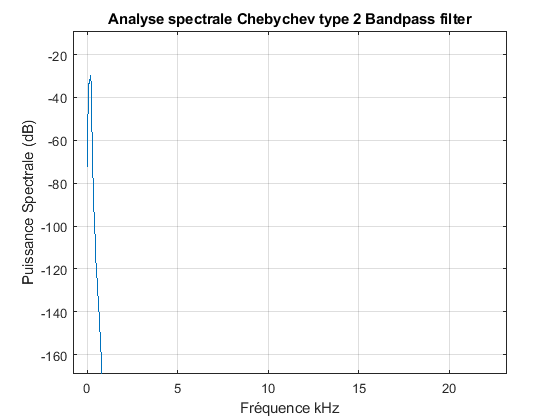

   
Fstop1 = 15;  % First Stopband Frequency
Fstop2 = 800;  % Second Stopband Frequency
Astop  = 130;   % Stopband Attenuation (dB)
filtOrder = 12; % Order

% Construct an FDESIGN object and call its CHEBY2 method.
h  = fdesign.bandpass('N,Fst1,Fst2,Ast', filtOrder, Fstop1, Fstop2, Astop, sampleRate);
cheby2 = design(h, 'cheby2');

resCheb = filter(cheby2,son_3_avec_perturbation);

figure
SpectralAnalyser(resCheb,sampleRate,frequencyLimits,0,[0 15]);
title('Analyse spectrale Chebychev type 2 Bandpass filter')

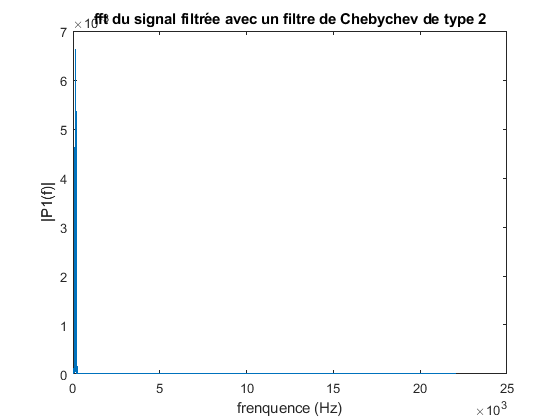

%xlim([0 20])
%ylim([-120 24])



figure
fftPlotter(resCheb,sampleRate)
title('fft du signal filtrée avec un filtre de Chebychev de type 2')


%sound(resCheb,sampleRate);
%audiowrite('Block\resCheb.wav',resCheb,sampleRate);

Essayns encore mais cette fois-ci  en avec la plage de fréquence trouvé avec l'analyse spectrale  de [20 1250] Hz. 

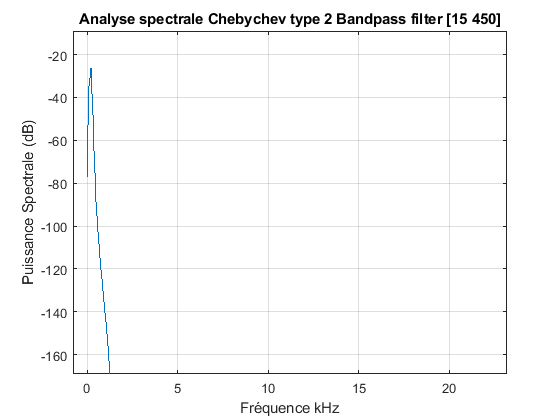

Fstop1 = 15;  % First Stopband Frequency
Fstop2 = 1250;  % Second Stopband Frequency
Astop  = 130;   % Stopband Attenuation (dB)
filtOrder = 12; % Order

% Construct an FDESIGN object and call its CHEBY2 method.
h  = fdesign.bandpass('N,Fst1,Fst2,Ast', filtOrder, Fstop1, Fstop2, Astop, sampleRate);
cheby2 = design(h, 'cheby2');

resCheb2 = filter(cheby2,son_3_avec_perturbation);

figure
SpectralAnalyser(resCheb2,sampleRate,frequencyLimits,0,[0 15]);
title('Analyse spectrale Chebychev type 2 Bandpass filter [15 450]')

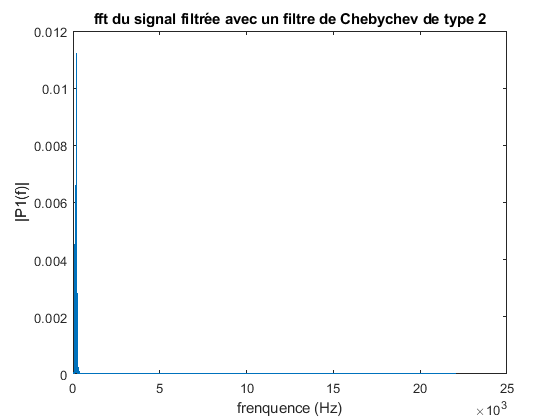

%xlim([0 20])
%ylim([-120 24])



figure
fftPlotter(resCheb2,sampleRate)
title('fft du signal filtrée avec un filtre de Chebychev de type 2')


%sound(resCheb2,sampleRate);
%audiowrite('Block\resCheb2.wav',resCheb2,sampleRate);

Il faut aussi prendre note qu'en augmentant l'ordre du filtre, il est possible d'améliorer la vitesse de transisition ainsi que la fidelité musicale en contre partie d'un bruit plus présent.

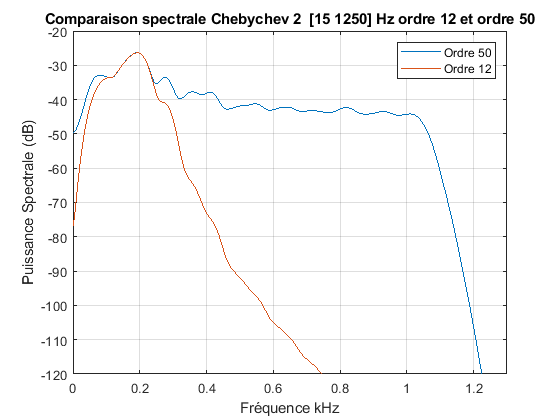

Fstop1 = 15;  % First Stopband Frequency
Fstop2 = 1250;  % Second Stopband Frequency
Astop  = 130;   % Stopband Attenuation (dB)
filtOrder = 50; % Order

% Construct an FDESIGN object and call its CHEBY2 method.
h  = fdesign.bandpass('N,Fst1,Fst2,Ast', filtOrder, Fstop1, Fstop2, Astop, sampleRate);
cheby2 = design(h, 'cheby2');

resCheb3 = filter(cheby2,son_3_avec_perturbation);

figure
SpectralAnalyser(resCheb3,sampleRate,frequencyLimits,0,[0 15]);

hold on
SpectralAnalyser(resCheb2,sampleRate,frequencyLimits,0,[0 15]);
title('Comparaison spectrale Chebychev 2  [15 1250] Hz ordre 12 et ordre 50')
hold off
legend('Ordre 50','Ordre 12')
xlim([0 1.3])
ylim([-120 -20])



%sound(resCheb3,sampleRate);
%audiowrite('Block\resCheb3.wav',resCheb3,sampleRate);


Il est possible de voir la différence de richesse du signal entre l'implémantation d'ordre 12 et 50. 

Sachant que la vitesse de transition semble avoir une importance. Essayons,  un filtre qui est reconnue pour avoir une d'emblé la meilleur vitesse de transition. 

Procedons à comparaison de ces deux filtres 

##  Eliptic bandpass

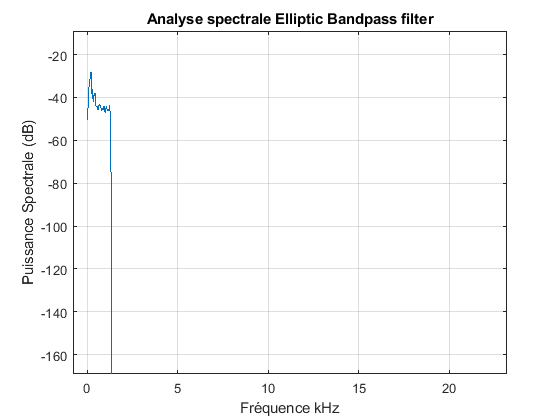



d = designfilt('bandpassiir','FilterOrder',filtOrder, ...
    'PassbandFrequency1',Fstop1,'PassbandFrequency2',Fstop2, ...
    'PassbandRipple',3, ...
    'StopbandAttenuation1',40,'StopbandAttenuation2',Astop, ...
    'SampleRate',sampleRate);

resEllip= filter(d,son_3_avec_perturbation);


figure
SpectralAnalyser(resEllip,sampleRate,frequencyLimits,0,[0 15]);
title('Analyse spectrale Elliptic Bandpass filter')

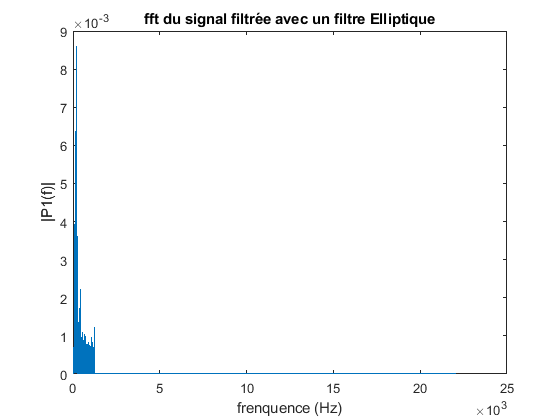



figure
fftPlotter(resEllip,sampleRate);
title('fft du signal filtrée avec un filtre Elliptique')



%sound(resEllip,sampleRate);
%audiowrite('Block\resEllip.wav',resEllip,sampleRate);

## Comparaison filtres passebande Chebychev type 2 et Elliptic pour des paramêtres égaux

En comparant les résultats opbtenues pou ces deux filtres. Il est préférable à l'oreile d'avoir une bande passante stable plustôt qu'une grande vitesse de transition.

Comparons ce filtre avec un avec un filtre qui est est reconnue pour avoir une la meilleure vitesse de transition. Rappelons que d'un point du vue théorique une vitesse de transition est inutile pour isoler une voix humaine car la voix humaine possède une gamme de fréquence qui n'est pas fix. Les plus grands avantages de filtres Eliiptiques sont doncs inutils.

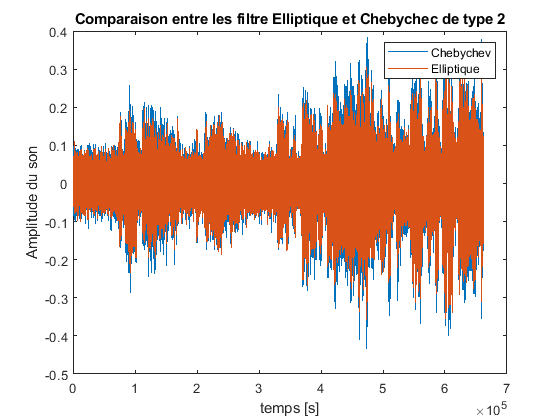

figure
plot(sample_point,resCheb3(:,1));
hold on;
plot(sample_point,resEllip(:,1));
title('Comparaison entre les filtre Elliptique et Chebychec de type 2')
xlabel('temps [s]')
ylabel('Amplitude du son')
legend('Chebychev','Elliptique');
hold off;

## Wavelet analysis

Comme 6iem filtre essayons quelque chose de différent. L'approche suivante est basé sur l'anayse par wavelets tel que définie [[https://www.hpl.hp.com/hpjournal/94dec/dec94a6a.pdf](https://www.hpl.hp.com/hpjournal/94dec/dec94a6a.pdf) ]. Contrairement aux séries de Fourier qui font du dévloppement sous fomre de série trigonométriques, les wavelets procède au développement de fonctions sous forme de translations et de dilatations. Le résultat est exprimé sous forme temporel ainsi que fréquencielle. En pratique les wavelets sont utilisées pour traiter des signaux qui sont non stationnaires telque la voix. 

L'approche suivant, est une fonction integré réduction de bruit par machine learning sur matlab qui utilise l'analyse par wavelets.

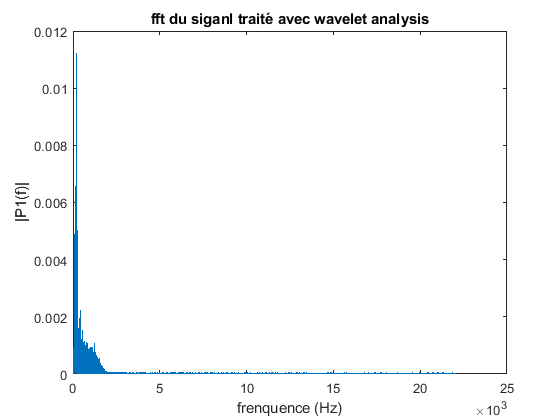

datsignal = son_3_avec_perturbation(:,1) ;



resDenoise = wdenoise(datsignal,4, ...
    'Wavelet', 'sym8', ...
    'DenoisingMethod', 'minimax',...
    'ThresholdRule', 'Hard', ...
    'NoiseEstimate', 'LevelDependent');

figure
fftPlotter(resDenoise,sampleRate);
title('fft du siganl traité avec wavelet analysis')


%sound(resDenoise,sampleRate);
%audiowrite('Block\resDenoise.wav',resDenoise,sampleRate);


L'avantage avec la dernière approche est qu'il n'est pas essentiel d'avoir des connaissances du signal d'entrée pour avoir des résultats.  Cependant il faut noter ce ce filtre as introduit des nouveau parasites au signal et que les résultats finaux sontmoindre que pour le filtres statiques. Les éssais de filtration par machine leaning ont été écourté faute de temps. 

## Conclusion 

Afin de bien traiter une signal avoir des connaisances du signal d'entrée et l'origine du bruit est essentiel afin d'avoir des bons résultats. Le fait de d'avoir le son pure en plus des outils  d'analyses tels que la fft et l'analtyse spectrale du son avant l'ajout du bruit gaussien nous a s permis de connaitre ses propriétés. De ces  connaissances, résultent de filtres concus pour isoler spécifiquement les fréquences dominates et de couper les parasites. La supréssion bruit par machine learning semble prometteur pour analsyer des bruits sans informations préallables. Cependant, si l'algorythme n'a pas été entrainé à voir les fréquences à isoler ; les résultats peuvent être aléatoires.